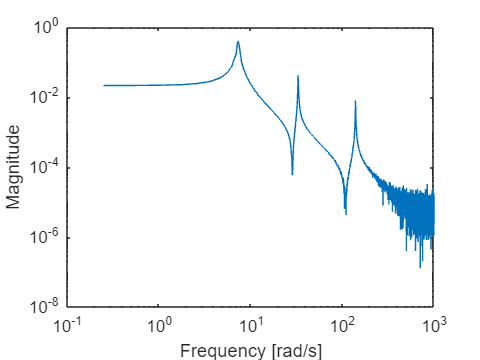

clear
addpath("frffit"); addpath("Assignments")
load("frfdata.mat")

bodeplm(hz,H1)

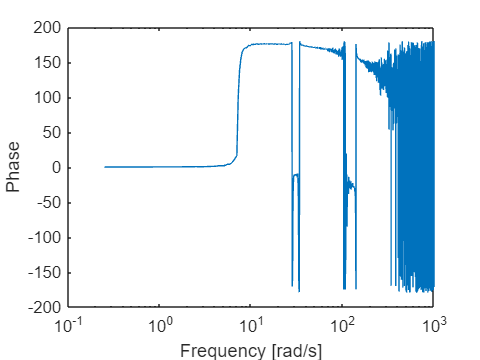

bodeplp(hz,H1)

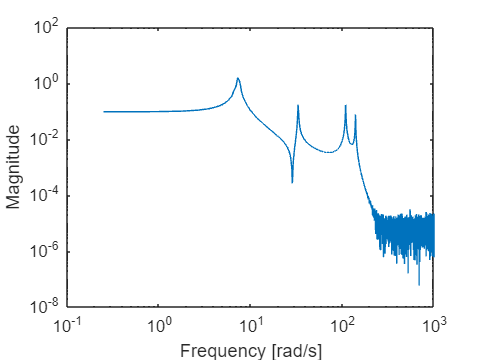


bodeplm(hz,H2)

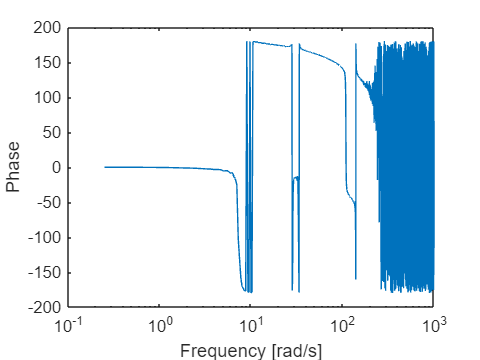

bodeplp(hz,H2)

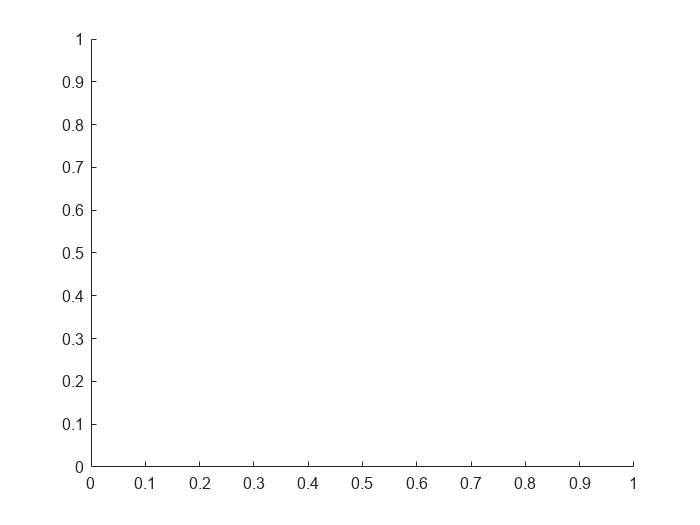

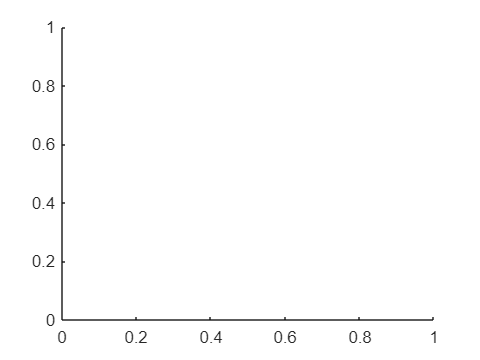

figure()
hold on

[num, den] = (frfit(H1,hz,[1+2+4, 1 + 1 + 4, 0], 1));

Frequency vector is linear; WF is therefore adjusted.
initial estimate of FRQLS
determination of initial errors
 
Building original data matrix
 
Start output error iterations
OE iteration 1; a/m-re of 1/den: 0.99364 215.6429
OE iteration 2; a/m-re of 1/den: 0.98404 63.5967
OE iteration 3; a/m-re of 1/den: 0.90165 22.0725
OE iteration 4; a/m-re of 1/den: 0.92728 11.6809


OE iteration 5; a/m-re of 1/den: 0.96535 1.1366


OE iteration 6; a/m-re of 1/den: 0.989 4.7858


OE iteration 7; a/m-re of 1/den: 0.88475 2.3671


OE iteration 8; a/m-re of 1/den: 0.22168 0.31614


OE iteration 9; a/m-re of 1/den: 0.059841 0.09106


OE iteration 10; a/m-re of 1/den: 0.004346 0.0066309


OE iteration 11; a/m-re of 1/den: 0.00032837 0.00049823


OE iteration 12; a/m-re of 1/den: 2.8222e-05 4.2284e-05


OE iteration 13; a/m-re of 1/den: 2.4082e-06 3.4759e-06


OE iteration 14; a/m-re of 1/den: 2.1436e-07 3.9894e-07


OE iteration 15; a/m-re of 1/den: 2.1955e-08 5.0455e-08
Linear step on numerator coefficients
norm = euclidian norm; error e(w):=sF(w)-s(w);
average relative error of s (are) := norm(e)/norm(sF)
maximum relative error of s (mre) := max(abs(e)./abs(sF)
are mre for the consecutive iterations:
   2.0299e+01   6.8992e+04
   3.0732e-01   7.4203e+01

 


H = tf(num,den)

H =
 
              92.34 s^5 - 1.802e04 s^4 + 4.613e07 s^3 - 6.962e08 s^2 + 1.398e12 s - 6.595e12
  -------------------------------------------------------------------------------------------------------
  s^7 + 6.484e-14 s^6 + 8.124e05 s^5 - 4.301e06 s^4 + 3.482e10 s^3 - 2.269e11 s^2 + 6.966e13 s - 3.217e14
 
Continuous-time transfer function.



figure()
bode(H)


[num,den] = (frsfit(H2,hz,[2+2+2+6, 2+4+2, 0], 1));

Frequency vector is linear; WF is therefore adjusted.
initial estimate of FRQLS
determination of initial errors
 
Building original data matrix
 
Start output error iterations
OE iteration 1; a/m-re of 1/den: 1 1.0041
OE iteration 2; a/m-re of 1/den: 0.98886 5266.2671


OE iteration 3; a/m-re of 1/den: 0.99883 49.5738


OE iteration 4; a/m-re of 1/den: 1.394 3388.2457


OE iteration 5; a/m-re of 1/den: 0.86302 40.31


OE iteration 6; a/m-re of 1/den: 0.90683 74.8687


OE iteration 7; a/m-re of 1/den: 0.68433 940.7656


OE iteration 8; a/m-re of 1/den: 1.3603 45.8263


OE iteration 9; a/m-re of 1/den: 0.44865 29.4133


OE iteration 10; a/m-re of 1/den: 0.74381 43.658


OE iteration 11; a/m-re of 1/den: 1.3386 37.6813


OE iteration 12; a/m-re of 1/den: 0.46356 26.1694


OE iteration 13; a/m-re of 1/den: 0.82973 39.8529


OE iteration 14; a/m-re of 1/den: 4.2378 37.1761


OE iteration 15; a/m-re of 1/den: 1.0009 17.063


OE iteration 16; a/m-re of 1/den: 0.90802 1429.188


OE iteration 17; a/m-re of 1/den: 0.75121 10.9969


OE iteration 18; a/m-re of 1/den: 0.39055 27.9925


OE iteration 19; a/m-re of 1/den: 0.058339 0.2444


OE iteration 20; a/m-re of 1/den: 0.012076 0.016722


OE iteration 21; a/m-re of 1/den: 0.00088679 0.0012116


OE iteration 22; a/m-re of 1/den: 0.00013625 0.00018819


OE iteration 23; a/m-re of 1/den: 1.2725e-05 1.7487e-05


OE iteration 24; a/m-re of 1/den: 1.6593e-06 2.2902e-06


OE iteration 25; a/m-re of 1/den: 1.7267e-07 2.3785e-07


OE iteration 26; a/m-re of 1/den: 2.0895e-08 2.8839e-08
Linear step on numerator coefficients
norm = euclidian norm; error e(w):=sF(w)-s(w);
average relative error of s (are) := norm(e)/norm(sF)
maximum relative error of s (mre) := max(abs(e)./abs(sF)
are mre for the consecutive iterations:
   4.4889e+01   3.6444e+07
   2.8355e-01   2.9075e+00

 
General Error occurred in WebControllerFactory::create()


H = tf(num,den)

figure()
bode(H)